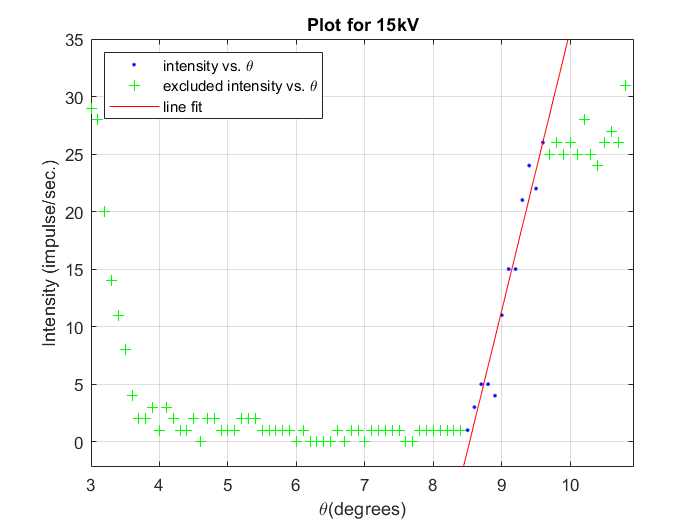

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( theta15kV, Rateat15kV );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 68 69 70 71 72 73 74 75 76 77 78 79] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'R15kV vs. theta15kV', 'Excluded R15kV vs. theta15kV', 'untitled fit 1', 'Location', 'NorthWest' );
% Label axes
xlabel theta15kV
ylabel R15kV
grid on

%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =       24.34  (20.1, 28.58)
 %      p2 =      -207.6  (-246, -169.2)

%Goodness of fit:
 % SSE: 51.79
  %R-square: 0.9424
  %Adjusted R-square: 0.9366
  %RMSE: 2.276
  
xlim([3.00 10.93])
ylim([-2.2 35.0])

legend({'intensity vs. \theta','excluded intensity vs. \theta','line fit'},'Location','northwest')
title('Plot for 15kV')
xlabel('\theta(degrees)')
ylabel('Intensity (impulse/sec.)')


%\theta_m=8.5292 \pm 1.085